# RVC 1, Ch 7.3 Inverse Kinematics

clear 
close all
clc
clear livescript

## Lec 05.4 (Ch 7.3) - Analytic Inverse Kinematics (Peter Corke's Toolbox)

Let's analyze the inverse kinematics for a 6 DoF robot. 

One important aspect of 6 DoF robots lies in their wrist. In particular, their 'spherical wrist'. 

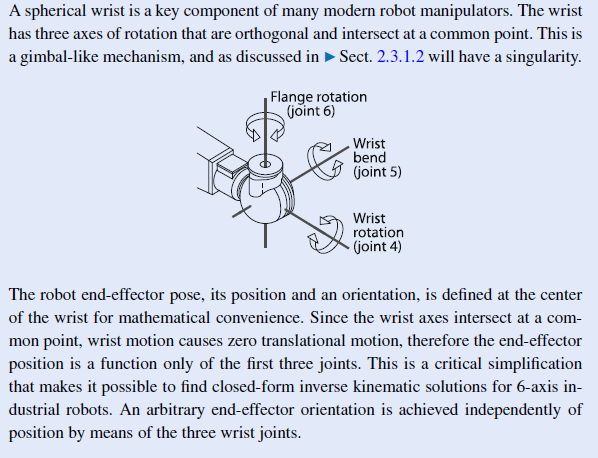

To analyze the Inverse kinematics we will set the stage with a current pose and a desire pose. 

We will compute the inverse kinematics of the desired pose and discover the joint angles necessary to reach that configuration. 

We will also plot it. 

Let's begin by loading the Puma 560 model:

mdl_puma560

Plot it's pose at qz. 

Note: Stack it on your ride side of the command window for best visualization.

p560.plot(qz)

Now, consider a desired target pose we would like our end-effector to reach:

T = transl(0.6, -0.25, 0)*rpy2tr(0,180,0, 'deg')

Let's superpose this target pose on top of the robot figure:

hold on,
trplot(T, 'rgb')

### ikine6s()

What would be the joint configuration required to get to this pose?

To compute it, we must use the **ikine6s()** method which is part of the SerialLink class. 

  % ikine6s documentation:
  % Q = R.ikine(T) are the joint coordinates (1xN) corresponding to the robot
  % end-effector pose T which is an SE3 object or homogenenous transform
  % matrix (4x4), and N is the number of robot joints.  This is a analytic
  % solution for a 6-axis robot with a spherical wrist (the most common form
  % for industrial robot arms).

Call the ikine6s with the end-effector pose as input:

q_target = p560.ikine6s(T)

Visualize this pose, which by default chooses a right-handed, elbow-up, not flipped configuration. 

p560.plot3d(q_target); % Or with link via: p560.plot(q_target, 'jvec')

## Lec 05.5 (Ch 7.3.1) - Configuration Change

Inverse kinematics may render different solutions depending on the structure of the robot.  We have seen a simple elbow-up, elbow-down configuration for the 2 DoF robot, that also exists here for the puma. 

In addition there will be a 'right-handed' and 'left-handed' configuration. 

The method ikine6s can bring up alternate configurations via string inputs as its 2nd argument.

Examples are: 

- left or right handed: 'l' or 'r' options

- elbow up or down: 'u', 'd'

- wrist flpped, not flipped: 'f','n'

Let's explore the possibilities.

Load your robot:

mdl_puma560

Create a desired pose:

T = transl(0.6, -0.25, 0)*rpy2tr(0,180,0, 'deg')

Compute the inverse kinematics via ikine6s and change the configuration via options:

- left or right handed: 'l' or 'r' options

- elbow up or down: 'u', 'd'

- wrist flpped, not flipped: 'f','n'.

Start by comparing right and left arm configurations for the puma 560. 

Right hand configuration:

qr = p560.ikine6s(T, 'r'), p560.plot3d(qr)

Left hand configuration:

ql = p560.ikine6s(T, 'l'), p560.plot3d(ql);

Now introduce elbow down alongside right configuration:

qrd = p560.ikine6s(T, 'rd'); p560.plot3d(qrd)

And the left-elbow-down configuration:

qld = p560.ikine6s(T, 'ld'); p560.plot3d(qld)

Generating trajectories 

Let's create a trajectory from the right-elbow-up configuration to the left-elbow up configuration to see how the robot might change its joint angle configuration to reach the alternate configuration. 

We can do this via jtraj:

qtraj = jtraj(qr,ql, 50);

Examine the size of qtraj:

size(qtraj)

Notice we have 50 time-steps each of 6 dimensions containing values for each of the six joint angles of the robot.

We can visualize the trajectory of the robot via SerialLink.plot() method:

p560.plot(qtraj)

Notice the end-effector ends where it started.

## Analytic Inverse Kinematics with the Matlab Robotic System Toolbox

Let us now study how to solve analytic inverse kinematics with the Matlab Robotic System Toolbox. 

We will start with the ABB IRB 1600 industrial robot and use the matlab robot system's toolbox to load it:

abb = loadrobot("abbIrb1600", DataFormat="row");

Visualize it:

abb.show

And show it's details:

abb.showdetails

### Analytical Inverse Kinematics

To solve the analytical inverse kinematics with the matlab robotics system toolbox, we will have to follow three steps:

- Create an `analyticalInverseKinematics` object

- Create an `generateIKFunction` for a specific kinematic group of the robot configuration

- Pass a target pose to the instantiated object of `generateIKFunction`

Let's take a look.

Before we can solve the inverse kinematics, we will have to create an [analyticalInverseKinematics](https://www.mathworks.com/help/robotics/ref/analyticalinversekinematics.html) object. 

aIK = analyticalInverseKinematics(abb);

This group can provide different solutions depending on what end-effector we choose: 

- link6 

- tool frame 

Both will still satisfy the spherical wrist constraint. This can be shown via showdetails:

aIK.showdetails

Note: 

You have the option to click whichever group you want to use with your mouse. The default group is set to use the last link in the structure (i.e. the tool). 

Once we have our aIK object, the next step is to crate a specific analytic function for the robot via the aIK [generateIKFunction](https://www.mathworks.com/help/robotics/ref/analyticalinversekinematics.generateikfunction.html)() method along with some 'function name':

abbIKFcn = aIK.generateIKFunction("ikIRB1600")

We are now able to compute the inverse kinematics given a particular pose. 

Create a random pose:

T = transl(0.75, 0, 0.5)*eul2tr(0,pi/2,0)

To solve for the required joint configuration, pass the pose T to our `abbIKFcn`. 

Note:

If there are more than one solution, it will show in each row. It is possible to get multiple solutions here:

qsol = abbIKFcn(T)

### Visualize

Visualize the robot via the show command which takes the robot and a joint angle configuration. 

show( abb,qsol(6,:) );

### Trajectory Generation across Configurations

We can set the first two solutions to 'right' and 'left' handed configurations:

qr = qsol(1,:);
ql = qsol(2,:);

Then generate a trajectory via jtraj:

qtraj = jtraj(qr, ql, 50); 

Visualize the trajectory via a for loop:

r = rateControl(10);
for i = 1:size(qtraj,1)
    abb.show(qtraj(i,:),FastUpdate=true,PreservePlot=false);
    r.waitfor;
end

## Lec 05.6 (Ch 7.3.2) Numerical Inverse Kinematics

To learn how to use numerical inverse kinematics let's start with a simple 2DoF robot. 

1. Load the robot and visualize it at the qz position:

mdl_planar2
p2.plot(qz)

2. Create a pose on the xy plane:

T = transl(1,1,0);

hold on;
trplot(T, 'rgb')

3. We are now read to try to solve for the numerical inverse kinematic method via the **SerialLink.ikine()** method

`Q = R.ikine(T, options)`

However the method benefits from options. Here are some definitions:

- T: pose from which you want to compute the inverse kinematics. Must be an SE3 object or homogeneous transform matrix.

- initialGues: this guess is a joint configuration of what might be closest to the answer. If you have no knowledge of this, use anything: qz, qn, etc. Default is all zeros.

- 'mask', M: useful when DoF is less than 6. Indicate over which spatial coordinates should it work (x,y,z,r,p,y). The mask vector only uses 1's and 0's. I.e. if you only care about the (x,y) position, the mask vector would be: 'mask', [1 1 0 0 0 0]

Let's call it:

q1 = p2.ikine( T, qz, 'mask', [1 1 0 0 0 0])

Let's visualize the position of the robot (call it from the command window):

p2.plot(q1)

The question now becomes, might I be able to extract a different joint angle configuration that might still reach that same pose?

We know the 2 DoF robot has elbow-down and elbow-up solutions. How might we get there?

You might try a different initial condition. Perhaps setting the first joint to 90 degrees:

q2 = p2.ikine( T, 'mask', [1 1 0 0 0 0], 'q0', [pi/2 0]) 
p2.plot(q2)

### Numerical Inverse Kinematics Puma 560 

Let's extend the concepts to the Puma 560. 

Load the robot and visualize it at qn:

mdl_puma560;
p560.plot(qn);

Create a target pose in degrees:

T_qn = p560.fkine(qn)   

Let's plot our target pose on top of the robot:

hold on
trplot(T_qn, 'rgb')

Compute the numerical inverse kinematics:

q1 = p560.ikine(T_qn)

Notice these solutions are very different to the original value of qn:

qn

However, a more important check is to see whether or not it reaches the correct end-effector pose. 

We can check that by using the q solution in our forward kinematics once again and compare with the original T_qn:

T_new = p560.fkine(q1)

Compare with T_qn:

T_qn

It is in fact the same pose. 

Let's visualize it and see if the end-effector reaches the desired pose:

p560.plot(q1) 

It indeed does, but with an elbow down configuration. 

How could we achieve the elbow up? A different initial guess? Try by completing the guess below

q2 = p560.ikine(T_qn, 'q0', [0, -pi/2 pi/2 0 0 0]) 

Plot it:

p560.plot(q2)

## Numerical Inverse Kinematics via Matlab's Robotic System Toolbox

To compute numberical inverse kinematics you will need to create a numerical solver object before you call the solver object with the input pose. 

Here is an overview of the steps:

- Load the robot

- Create target pose 

- Create a numerical inverse kinematics solver object via `inverseKinematics`

- Use that object to carry out the numerical IK computation

Let's take a look:

Begging by loading your abb robot:

robot = loadrobot("abbIrb1600", DataFormat="row")

robot =   rigidBodyTree with properties:

     NumBodies: 7
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'link_1'  'link_2'  'link_3'  'link_4'  'link_5'  'link_6'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'row'


Generate a random joint angle configuration for the robot via `randomConfiguration`:

qrand = randomConfiguration(robot)

qrand =     1.3364    0.4116   -1.7171   -3.0744    0.7305   -6.3889


We will want to get a pose from qrand. To do this, we will employ the `rigidBodyTree.getTransform()` which requires the joint angle and target frame (i.e. the end-effector frame) name. 

We can get the name of body name frames via showdetails:

robot.showdetails

--------------------
Robot: (7 bodies)

 Idx     Body Name           Joint Name           Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------           ----------           ----------     ----------------   ----------------
   1        link_1              joint_1             revolute         base_link(0)   link_2(2)  
   2        link_2              joint_2             revolute            link_1(1)   link_3(3)  
   3        link_3              joint_3             revolute            link_2(2)   link_4(4)  
   4        link_4              joint_4             revolute            link_3(3)   link_5(5)  
   5        link_5              joint_5             revolute            link_4(4)   link_6(6)  
   6        link_6              joint_6             revolute            link_5(5)   tool0(7)  
   7         tool0        joint_6-tool0                fixed            link_6(6)   
--------------------


For example, panda_rightfinger.

Compute the forward kinematics:

T = robot.getTransform(qrand,"tool0")

T =    -0.2616    0.9633   -0.0603    0.1116
   -0.8566   -0.2605   -0.4454    0.4548
   -0.4447   -0.0649    0.8933    1.5589
         0         0         0    1.0000


### InverseKinematics Class

To compute the inverseKinematics we can instantiate an object of this class by passing the 'robot' or rigidBodyTree as an argument. 

This object is in fact called a solver object that we will use to solve the numerical problem. 

robot_ik_num = inverseKinematics(RigidBodyTree=robot)

robot_ik_num =   inverseKinematics with properties:

       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


Numerical IK Solvers require quite a number of parameters. The `robot_ik_num` solver will now work as a function that requires the following:

`[QSol, solnInfo] = robot_ik_num('link_name', tform, weights, initialGuess);`

See the full documentation [here](https://www.mathworks.com/help/robotics/ref/inversekinematics-system-object.html). In brief:

- 'link_name' - name to frame for your end-effector in your rigidBodyTree

- tform           - pose from which you want to compute the inverse kinematics

- weights       - is an initialization of weights for a 1xN. In optimization problems we needs weights. They acts as coefficients of a polynomial. 

- initialGues   - this guess is a joint configuration of what might be closest to the answer. If you have no knowledge of this, use the home configuration.

The method will output two variables:

- QSol - 1xN inverse kinematic sol

- solInfo - structure with information about how the algo ran. See documantion for more. 

We can finally call it:

q_home = robot.homeConfiguration

q_home =      0     0     0     0     0     0


[qsol,solinfo] = robot_ik_num("tool0",...  % end-effector body name
                        T,...              % current pose 
                        ones(1,6),...      % weights
                        q_home)            % joint angle guess

qsol =     1.3364    0.2482   -1.4245   -3.0824    0.8595   -0.0942


solinfo = struct with fields:
           Iterations: 160
    NumRandomRestarts: 4
        PoseErrorNorm: 5.4964e-09
             ExitFlag: 1
               Status: 'success'


Was the solution accurate?

It was produced from q_home, let's compare the two:

qrand

qrand =     1.3364    0.4116   -1.7171   -3.0744    0.7305   -6.3889


qsol

qsol =     1.3364    0.2482   -1.4245   -3.0824    0.8595   -0.0942


abs(qrand-qsol)

ans =     0.0000    0.1634    0.2927    0.0080    0.1290    6.2946


This certainly a very different pose. The next question we can ask is does it produce the same pose?

We began with T:

T

T =    -0.2616    0.9633   -0.0603    0.1116
   -0.8566   -0.2605   -0.4454    0.4548
   -0.4447   -0.0649    0.8933    1.5589
         0         0         0    1.0000


If we use qsol with forward kinematics we have:

T_new = robot.getTransform(qsol,'tool0')

T_new =    -0.2616    0.9633   -0.0603    0.1116
   -0.8566   -0.2605   -0.4454    0.4548
   -0.4447   -0.0649    0.8933    1.5589
         0         0         0    1.0000


Notice that in this case we do have exactly the same pose. This means the numerical inverse kinematics found a solution for the pose but with a different configuration! This is often the case with numerical methods. You cannot easily control the configuration achieved for the solution.

### TODO: Timing

The last analysis that is worth having is to compare the timing of the analytical method vs the numerical method. 

We can use the `timeit` method to time the execution length of a funciton. 

Before comparing, let's quickly create an IK_function for the ABB robot:

robot_ik = analyticalInverseKinematics(robot);
robot_ik_func = generateIKFunction(robot_ik, 'robot_ik_handle')

robot_ik_func = function_handle with value:
    @robot_ik_handle


Now we we can compare the *numerical* robot_ik_num to the *analytical* robot_ik_func.

Numerical method:

tNumericalIK = timeit(@() robot_ik_num("tool0",T,ones(1,6),q_home))

tNumericalIK = 0.0321

Analytic method:

tAnalyticalIK = timeit(@() robot_ik_func(T))

tAnalyticalIK = 0.0013

Difference:

tNumericalIK / tAnalyticalIK

ans = 24.8420

So you can see the analytic method is faster than the numerical method. 

An implemention of this algorithm in C++ would run faster than matlab, as matlab is an ***interpreted langauge***.

## Lec 05.8 (ch7.3) - Practical Considerations

### No Solutions

It is possible that a desired pose yields no joint angle solution - simply because the limitations in the robot joints and link lengths do not allow it to reach that pose - aka ***Reachability***.

Let's illustrate. 

Create a desired pose too far out of the reach of the robot:

mdl_puma560

p560.ikine6s( SE3(3, 0, 0) )

ans =    NaN   NaN   NaN   NaN   NaN   NaN


### Singularities

Another scenario and more critical one occurs when there is a singularity. 

The main cause are gymbal lock problems: specially in spherical wrists where two independent frames are parallel to each other (usually frame 4 and 6). 

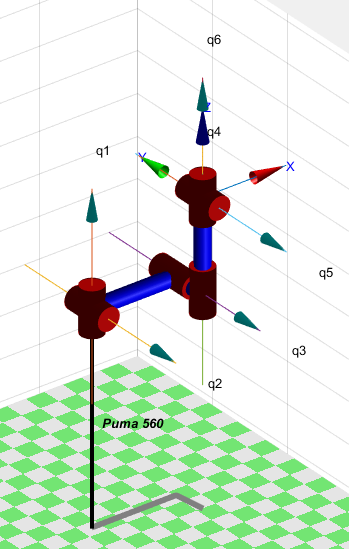

This may happens when joint5 is at such angle that 4 and 6 are aligned:

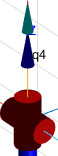

When this happens, joint 6 and joint 4 will both represent the same rotation instead of independent rotations. 

The best way to remove the singularity is ensuring that joint 5 does not allow this happen. In the puma560 robot, we do not want joint 5 to be zero.

Consider a gymbal lock configuration where q5 is zero:

q = [0 pi/4 pi 0.1 0 0.2] % q5 = 0

q =          0    0.7854    3.1416    0.1000         0    0.2000


The IK solution is:

p560.ikine6s( p560.fkine(q), 'rd')

ans =    -0.0000   -0.8335    0.0940    3.1416    1.6166   -2.8416


Notice the result of q4 and q6 (q5 reamins 0): the values for q4 and q6 are different than the originally set values of 0.1 and 0.2, but their sum adds up to what the original sum would be 0.3.

## Lec 05.9 (ch7.3) - Redundant Robots 

As mentioned in the lecture, redundant robots have an infinite number of configurations. For this reason, we cannot use analytic IK solutions. We must rely on numerical IK computations. 

Let's explore a robot with a large dimensional joint configuration called `mdl_hyper3d`. 

This model takes in an argument for number of joints. We will call it for 10 joints.

mdl_hyper3d(20)

The instantiated SerialLink object is called `h3d` and we also have access to qz which sets all 10 joints to zero

h3d

 
h3d = 
 
hyper3d:: 20 axis, RRRRRRRRRRRRRRRRRRRR, stdDH, slowRNE          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|       0.05|     1.5708|          0|
|  2|         q2|          0|       0.05|     1.5708|          0|
|  3|         q3|          0|       0.05|     1.5708|          0|
|  4|         q4|          0|       0.05|     1.5708|          0|
|  5|         q5|          0|       0.05|     1.5708|          0|
|  6|         q6|          0|       0.05|     1.5708|          0|
|  7|         q7|          0|       0.05|     1.5708|          0|
|  8|         q8|          0|       0.05|     1.5708|          0|
|  9|         q9|          0|       0.05|     1.5708|          0|
| 10|        q10|          0|       0.05|     1.5708|          0|
| 11|        q11|          0|       0.05|     1.5708|          0|

qz

qz =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Notice each joint is just 5cm long.

Set a desired pose:

T = transl(0.5, 0, 0.25)*eul2tr(0,pi/2,0)

T =          0         0    1.0000    0.5000
         0    1.0000         0         0
   -1.0000         0         0    0.2500
         0         0         0    1.0000


Let us now compute the numeric IKs using ikine and an initial guess of joint  angles qz:

q = h3d.ikine(T,qz)

q =     0.0000    0.6248   -0.0000   -0.5332   -0.0000    0.3026    0.0000    0.0020   -0.0000   -0.3180    0.0000    0.5831   -0.0000   -0.7301    0.0000    0.7075    0.0000   -0.5119   -0.0000    0.1788


The result is a 1x20 vector with the necessary joint angles to reach that pose. 

We can verify by running the forward kinematics and recovering the initial pose:

T_h3d = h3d.fkine(q)

 

T_h3d = 
   -0.0000         0         1       0.5
         0         1         0         0
        -1         0   -0.0000      0.25
         0         0         0         1


We can verify they are identical. 

Finally, let's plot this configuration:

h3d.plot(q)

## Lec 05.10 (ch7.3) - Joint Interpolated Motions

In this section, we will explore a specific type of trajectory called 'joint interpolated motions' using jtraj.

As an overview:

- Load a robot

- Create a starting and goal pose

- Convert poses to start and ending joint angles via IKs

- Use jtraj to create a multi-dimensional joint angle trajectory

- Analyze the properties of such trajectory

1. Load the robot:

mdl_puma560

2 Define start and goal poses:

TA = transl(0.4, 0.2, 0) * trotx(pi)

TA =     1.0000         0         0    0.4000
         0   -1.0000         0    0.2000
         0         0   -1.0000         0
         0         0         0    1.0000


TB = transl(0.4, -0.2, 0) * trotx(pi/2)

TB =     1.0000         0         0    0.4000
         0         0   -1.0000   -0.2000
         0    1.0000         0         0
         0         0         0    1.0000


3 Convert poses to corresponding joint angle configurations via IKs:

qA = p560.ikine6s(TA)

qA =     3.2631    2.0791    0.5992   -0.0000    0.4633    0.1215


qB = p560.ikine6s(TB)

qB =     2.3358    2.0791    0.5992   -2.3209    1.2425    1.2377


4. Generate a joint angle trajectory with jtraj:

qq = jtraj(qA,qB,50)

qq =     3.2631    2.0791    0.5992   -0.0000    0.4633    0.1215
    3.2630    2.0791    0.5992   -0.0002    0.4634    0.1216
    3.2625    2.0791    0.5992   -0.0015    0.4638    0.1222
    3.2611    2.0791    0.5992   -0.0048    0.4649    0.1238
    3.2586    2.0791    0.5992   -0.0111    0.4670    0.1268
    3.2547    2.0791    0.5992   -0.0210    0.4704    0.1316
    3.2490    2.0791    0.5992   -0.0352    0.4751    0.1384
    3.2415    2.0791    0.5992   -0.0540    0.4814    0.1475
    3.2320    2.0791    0.5992   -0.0779    0.4895    0.1589
    3.2203    2.0791    0.5992   -0.1071    0.4993    0.1730


### Analysis

Let's now visualize the robot trajectory

p560.plot(qq)

By looking at the trajectory directly it is hard to get an inuitition of the details of changes in joint angles. 

We can plot the six joint values over time as follows:

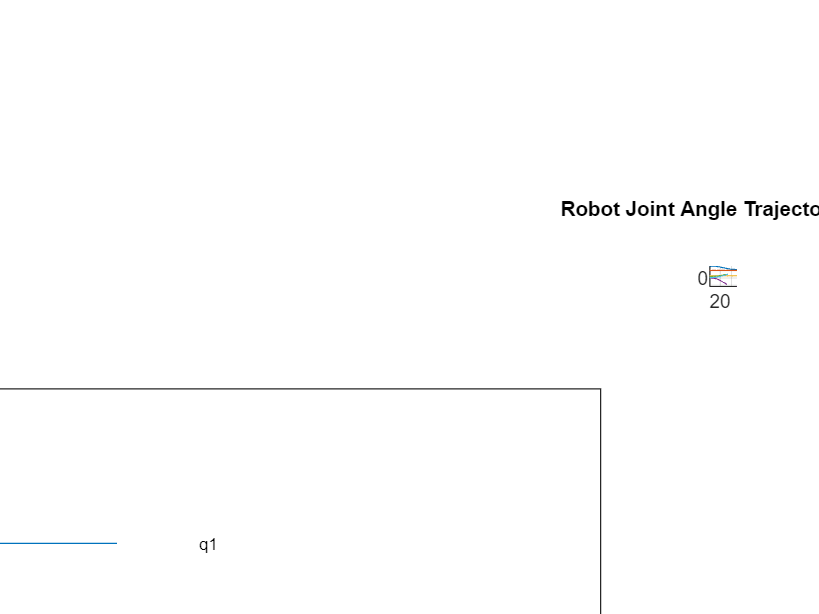

figure(2), grid on
qplot(qq); 
xlabel('time'); 
ylabel('q - joint angle configuration'); 
title('Robot Joint Angle Trajectory Plot')

The next step is to analyze how the position and orientation change over time. 

We will want to ask questions like: does the arm move in a straight line?

Start by computing the forward kinematics of the trajectory and then plotting:

TT = p560.fkine(qq);
size(TT)

ans =      1    50


Now save only the (x,y,z) coordinates  by extracting them via the .t member of the SerialRobot class:

pos = zeros(3,length(TT));
ori = zeros(3,length(TT));

pos = TT.transl

pos =     0.4000    0.2000    0.0000
    0.4000    0.2000    0.0000
    0.4001    0.1998    0.0000
    0.4004    0.1992    0.0000
    0.4009    0.1982    0.0000
    0.4017    0.1966    0.0000
    0.4028    0.1944    0.0000
    0.4042    0.1913    0.0000
    0.4060    0.1875    0.0000
    0.4082    0.1827    0.0000


ori = tr2rpy(TT.R)

ori =    -3.1416    0.0000    0.0000
    3.1415    0.0001    0.0000
    3.1409    0.0004    0.0000
    3.1392    0.0014    0.0001
    3.1362    0.0031    0.0001
    3.1313    0.0059    0.0002
    3.1244    0.0098    0.0003
    3.1150    0.0150    0.0003
    3.1029    0.0215    0.0002
    3.0879    0.0294   -0.0001


Plot the position:

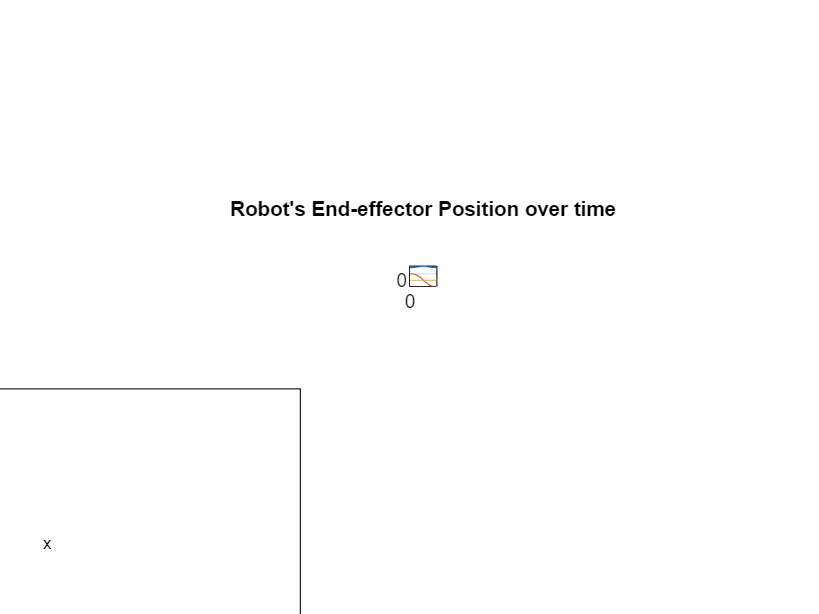

plot(pos); grid on

xlabel('Timesteps (t)')
ylabel('Magnitude')
title("Robot's End-effector Position over time")
legend("x","y","z")

**Questions:**

Study the plot. Are there any results that surprise you?

To simplify the analysis, we can also plot the trajectory along the x- and y-axis as a coordinate map. 

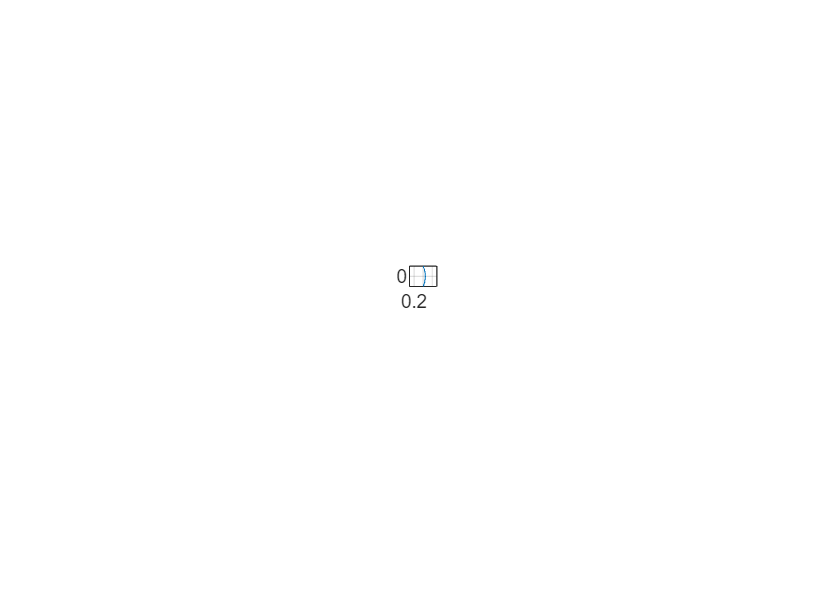

plot(pos(:,1), pos(:,2));  

axis([0.1, 0.7, -0.2, 0.2]); 
xlabel('x'); ylabel('y'); grid on

**Questions:**

Is this a straight line motion?

Plot the orientation:

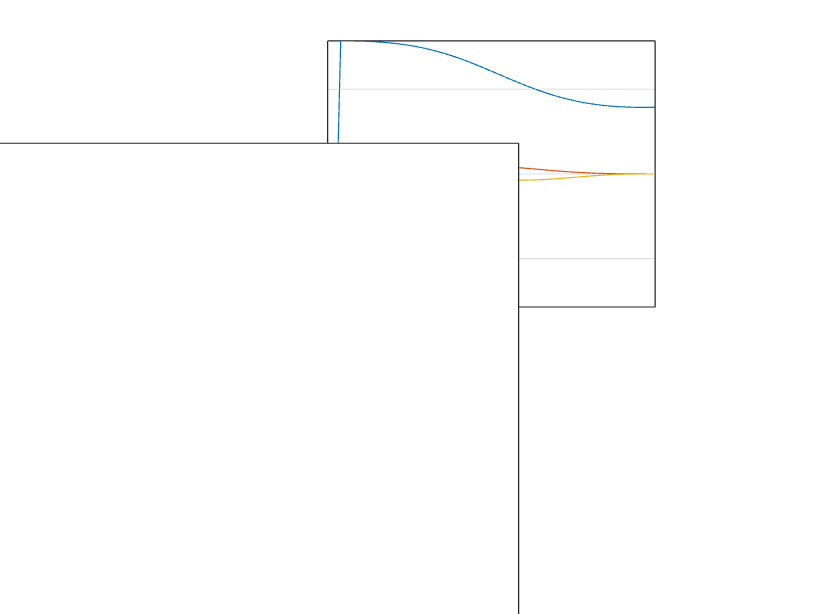

figure(3), 
plot(ori); grid on; legend("roll", "pitch", "yaw")

**Questions:**

Do you notice how the pitch starts and end at 0, but half-way through it moves away from 0?

This is not a fixed orientation either. 

When might this not be okay or not okay for a robot motion?

## Lec 05.11 (ch7.3) - Cartesian Interpolated Motion

If we wish to create a straight line trajectory (even with a fixed orientation), we need a different approach. 

Instead of interpolating the joint angles, we need to interpolate the poses. To this end, we can leverage the method `ctraj(). `If we have the same poses as before:

TA = transl(0.4, 0.4, 0)* trotx(pi)

TA =     1.0000         0         0    0.4000
         0   -1.0000         0    0.4000
         0         0   -1.0000         0
         0         0         0    1.0000


TB = transl(0.4, -0.4, 0)* trotx(pi/2)

TB =     1.0000         0         0    0.4000
         0         0   -1.0000   -0.4000
         0    1.0000         0         0
         0         0         0    1.0000


We an create the Cartesian trajectory as:

TT = ctraj(TA,TB, 50);
size(TT)

ans =      4     4    50


### Position and Orientation Visualization

We can visualize the position directly.

Decompose the homogeneous transform trajectory into a set of positions and orientations via `tr2rt`:

[R,pos] = tr2rt(TT);

Plot set of (x's and y's):

plot(pos(:,1), pos(:,2));  

And adjust their axes for better viewing:

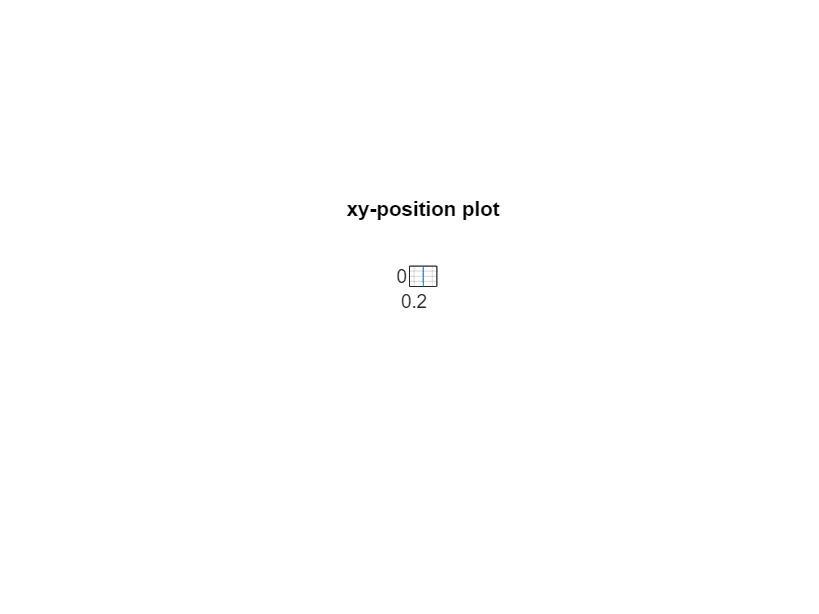

axis([0.1, 0.7, -0.4, 0.4]); grid on;
xlabel('x'); ylabel('y'); title('xy-position plot'); legend('off')

We can also plot the orientation as rpy angles.

Convert the rotation matrix to rpy angles:

rpy = tr2rpy(R);

Plot the rpy angles (best seen in the command window):

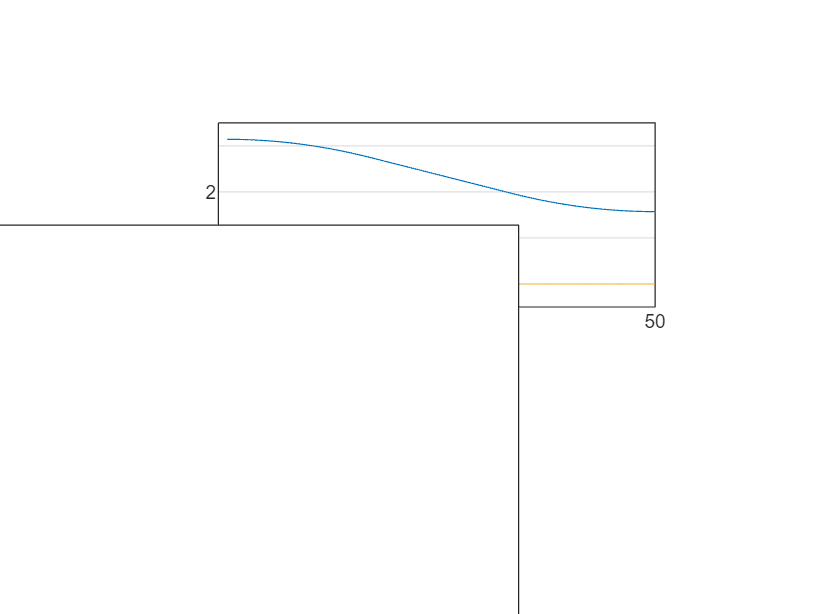

figure(3), 
plot( rpy ); grid on; 
axis([0,50,-0.5, 3.5])
legend('roll', 'pitch', 'yaw')

### Robot Trajectory Visualization

Finally, let's visualize the trajectory directly on a robot like the p560.

- Load the robot

- Compute the IKs of TT

- Do robot.plot

mdl_puma560;
qq = p560.ikine6s(TT)

qq =     3.6585    2.2532    0.2515   -0.0000    0.6368    0.5169
    3.6573    2.2524    0.2532   -0.0022    0.6367    0.5175
    3.6537    2.2500    0.2581   -0.0086    0.6365    0.5191
    3.6477    2.2459    0.2662   -0.0195    0.6360    0.5218
    3.6391    2.2403    0.2775   -0.0349    0.6354    0.5257
    3.6280    2.2331    0.2918   -0.0549    0.6347    0.5309
    3.6142    2.2245    0.3090   -0.0797    0.6338    0.5374
    3.5975    2.2145    0.3289   -0.1096    0.6328    0.5455
    3.5778    2.2032    0.3514   -0.1449    0.6319    0.5551
    3.5549    2.1908    0.3763   -0.1857    0.6309    0.5665


Plot (best shown in the command window)

p560.plot(qq, 'view', [90,0]); 

Notice how the position stays fixed as the orientation is updated. 

## For yout to try

Consider the problem of having a robot arm wiping a table in straight lines. 

You do not want the orientation to change. 

How would you change the code above to do that?

TODO: consider adding

[https://www.mathworks.com/help/robotics/ug/plan-a-reaching-trajectory-with-kinematic-constraints.html](https://www.mathworks.com/help/robotics/ug/plan-a-reaching-trajectory-with-kinematic-constraints.html)